# Proyecto Final: Moviles y Gravedad Sol, Tierra, Luna

## **Algoritmos Numéricos por Computadora**

## Manuel Fernández 166496

## Bernardo Altamirano 167881

## Santiago Borobia 165323

## Introducción

A continuación, se presenta un modelo del sistema plantario compuesto por el Sol, la Tierra y la Luna. El código presentado permite conocer las trayectorias aproximadas de la Tierra y la Luna, al orbitar al rededor del Sol. Es importante notar que la Luna orbita a su vez alrededor de la Tierra. 

Estas trayectorias se obtienen al analizar tanto la velociad como la aceleración de los cuerpos en el tiempo. Al depender ambos valores del tiempo, el sistema es cambiante por lo que lo analizaremos como un sistema dinámico. Es por esto que la resolución del problema se apoya de una herramienta llamanda "ivps" que es una función que soluciona sistemas dinámicos a partir de valores iniciales.

## Planteaminto del Problema

Para analizar correctamente el sistema Sol-Tierra-Luna lo dividiremos en dos subsitemas que conviven entre si. El primero, Sol-Tierra y el segundo, Tierra-Luna.

Por un lado, tenemos la Tierra orbitando al Sol. El Sol se encuentra en el origen de nuestro sistema, mientras que la Tierra se encuentra a una distancia total, sobre el eje x, que se conforma por el radio del Sol, más su distancia a la Tierra (rS+hT). Por lo tanto, la Tierra gira al rededor del Sol sobre el plano x-y. Esto se ilustra mejor en la imagen siguiente.

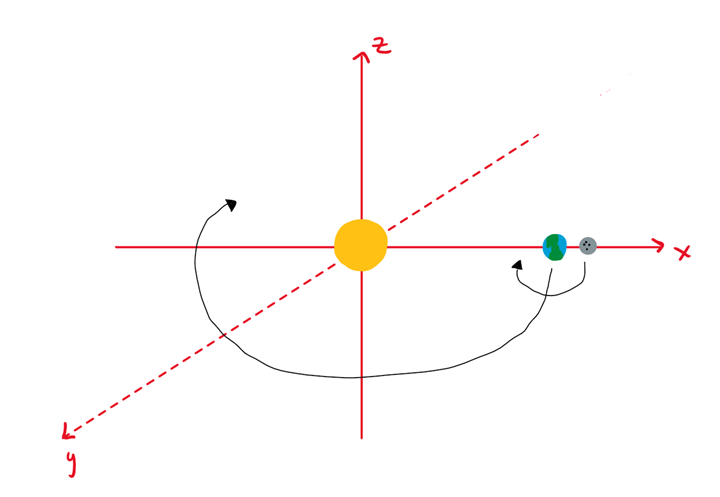

Por otro lado, tenemos a la Luna orbitando a la Tierra sobre el plano x-y, a una distancia que se conforma, en un tiempo inicial, a partir de la distancia de la Tierra al Sol, el radio de la Tierra y la distancia de la Tierra a la Luna (rS+hT+rT+hL). Esto se ilustra mejor en la imagen anterios y siguiente.

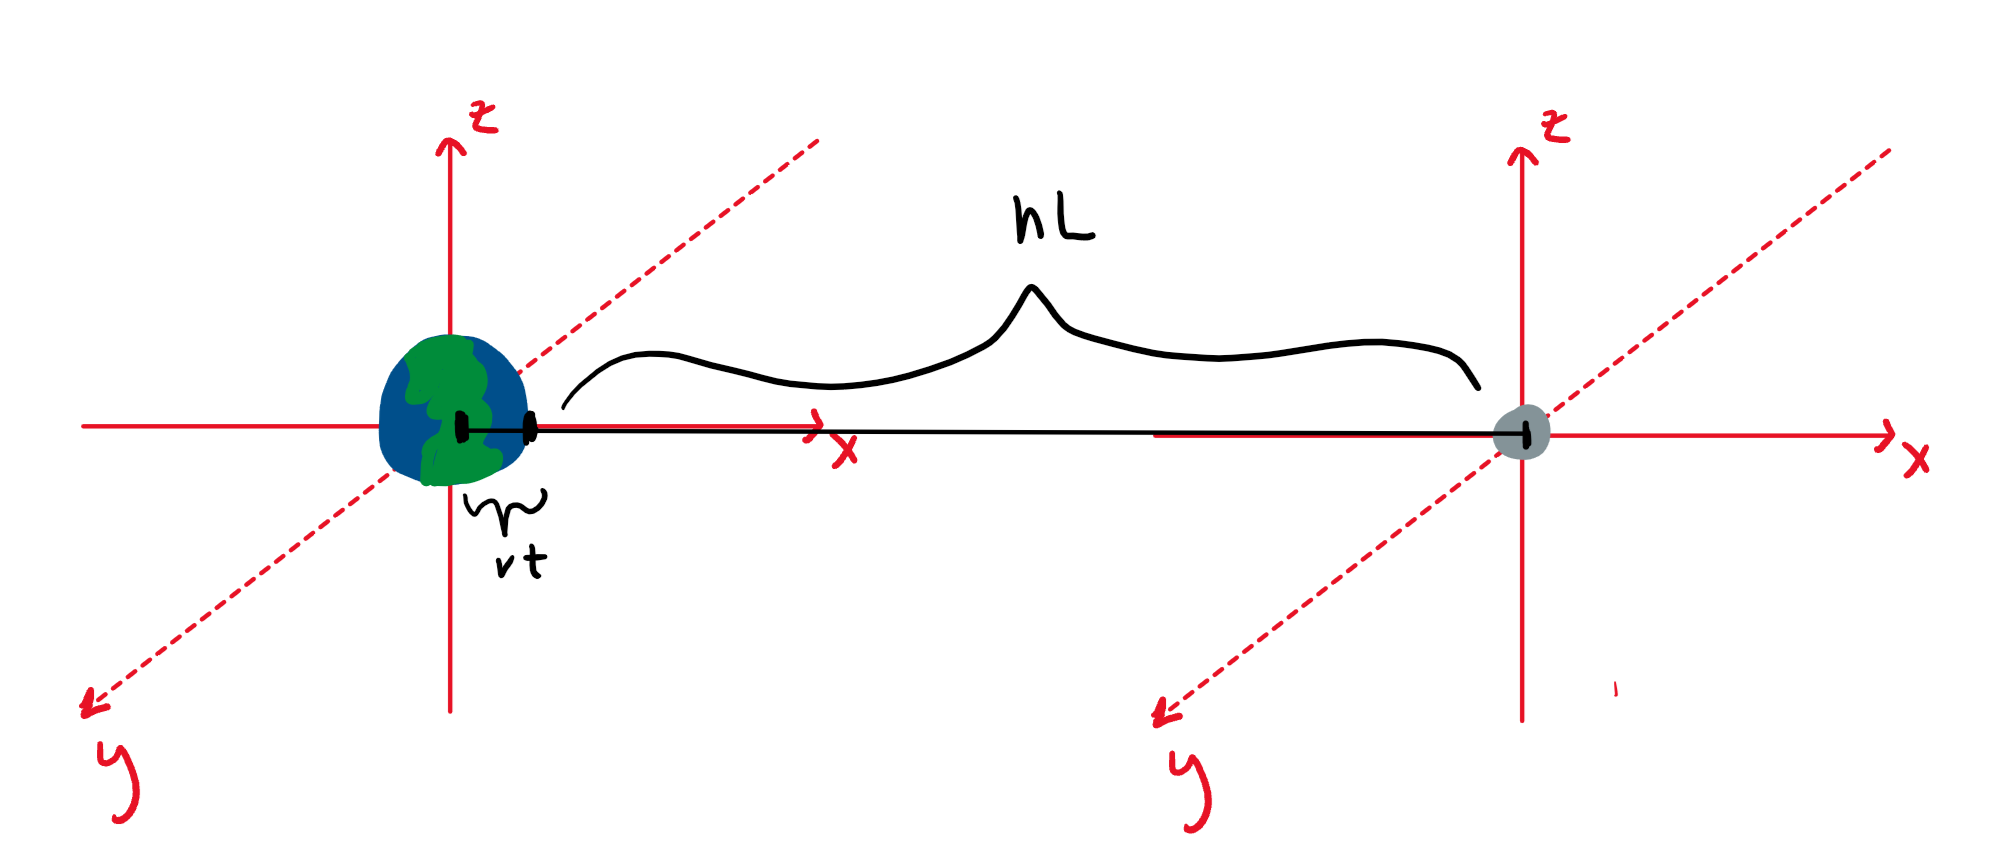

## El Sistema Dinámico

Como mencionamos anteriormente, el problema plantea un sistema que cambia en el tiempo. 

Entonces, sabiendo que la aceleracion es la segunda derivada de la posicion, y la velocidad es, a su vez, la primera derivada; si conociermos estos datos, podriamos modelar la posición de estos cuerpos resolviendo el siguiente sistema:

dy/dt = f(t,y)


$$\mathrm{y'}=\left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack$$


Esto se debe a que la solución sería un vector con la posición y la velocidad a lo largo del tiempo.


$$y=\left\lbrack \begin{array}{c}
r\\
v
\end{array}\right\rbrack$$


## Cálculo de la velociad y la aceleración (ydot)

Entonces, como dijimos anteriormente, requerimos encontrar tanto la velocidad como la aceleración de los cuerpos bajo estudio. 

Para encontrar la velocidad, partimos de la sigueinte formula.

Sea M la masa de un objeto 1 "estacionario", sea v la velocidad de otro objeto 2 que se mueve al rededor del primero y sea r el radio que va del primer objeto al segundo, entonces sabemos lo siguiente:


$$M_1 =\frac{{V_2 }^2 r}{G}$$


Por lo tanto, si despejamos la velocidad del segundo objeto tenemos que:


$$V_2 =\sqrt{\frac{GM_1 }{r}}$$


Es decir, la velocidad se calcula con respecto a los cuerpos con los que se esta interactuando dentro de un espacio de estudio. Más adelante explicaremos como manejaremos estas relaciones.

Para encontrar la aceleracion, utilizamos la función ydot. Esta función parte de la siguiente formula:


$$F=m\;a$$


Como ya conocemos la masa, por el cálculo anterior, no queda más que encontrar la fuerza para asi despejar la aceleración. Sabemos que la formula de la fuerza gravitacional entre dos cuerpos es la sigueinte:


$$F=G\frac{\mathrm{m1}\;\mathrm{m2}}{d^2 }$$


Esta formula, tambien se puede expresar de la siguiente manera:


$$F=G\frac{\textrm{m1}\;\textrm{m2}}{|d|}\hat{u}$$


Siendo |d| la norma de la distancia entre los objetos y $\hat{u}$ un vector unitario de dirección.

Es importante mencionar que estaremos considerando la fuerza que existe entre el Sol y la Tierra, la fuerza que existe entre el Sol y la Luna y la fuerza que existe entre la Tierra y la Luna. Por lo que haremos estos casos de forma separada y luego analizaremos todos como un solo sistema para poder calcular la aceleración cada cuerpo a partir de la fuerza resultante que experimenta dicho cuerpo.


$$a=\frac{F\;\mathrm{resultante}}{m}$$


## IVPS

Ivps es una función utilizada para resolver ecuaciones de sistemas dinámicos con condiciones iniciales. Se trata de un conjunto de 5 distintos métodos: Euler, Midpoint, Trapecio, RK4 y Ralston. Cada método obtiene una función a partir de su derivada y una condición inicial. Es decir, sabiendo como cambia la función objetivo en el tiempo, y el valor de ésta en el tiempo 0, se obtiene la función objetivo como tal. 

IVPS puede ser utilizado para calcular varias funciones simultáneamente a partir de sus derivadas. Entonces, puede resolver un problema de segundo orden si este se transforma por dos problemas de primer orden (la segunda derivada da la solución de la primera derivada, y esta última da la solución deseada). Además, se ha generalizado este "solucionador de sistemas dinámicos" para que pueda resolver problemas en cualquier dimensión n.

El proceso que se emplea es el siguiente:

- Se reciben como parámetros: un vector de derivadas de las funciones objetivo (f), el rango de tiempo que se requiere analizar [, ], el vector de condiciones iniciales (), el paso entre cada unidad de tiempo (h) y el # del método que se desea utilizar (1 a 5).

- A partir el punto de la condición inicial de cada función, se obtiene una dirección de crecimiento para obtener el siguiente punto de la misma función. Esta dirección se calcula dependiendo el método elegido en el solucionador.

- La dirección de crecimiento, en general, se calcula a partir de la derivada de la función objetivo correspondiente, obteniendo un "promedio de pendientes" en un punto, para conocer un aproximado "hacia dónde se va" al punto que le sigue.

- Con esta dirección, el siguiente punto se calcula haciendo: .

- Se repiten los pasos 3 y 4 hasta llenar cada punto desde hasta (avanzando en saltos de h).

En este trabajo, utilizamos IVPS para resolver el sistema dinámico que se mencionó más arriba, donde se necesita conocer la posición de la Tierra y de la Luna a partir de la ecuación de su aceleración (un problema de segundo orden, transformado en 2 de primer orden para cada cuerpo). Cabe mencionar que, en este problema, se está trabajando en 3ra dimensión, por lo que la generalización del IVPS fue necesaria para poder utilizarlo. Así, en cada iteración, se calculan las 3 coordenadas (x,y,z) de la posición de los cuerpos en el tiempo i.

## Notación y construcción de vectores

r0 : 3 X 3


$$r_0 =\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{c}
r_{0\;} \;\mathrm{Sol}\\
r_{0\;} \;\mathrm{Tierra}\\
r_{0\;} \;\mathrm{Luna}
\end{array}\right\rbrack$$


v0 : 3 X 3


$$v_0 =\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack 
\end{array}\right\rbrack =\;\left\lbrack \begin{array}{c}
v_{0\;} \;\textrm{Sol}\\
v_{0\;} \;\textrm{Tierra}\\
v_{0\;} \;\textrm{Luna}
\end{array}\right\rbrack$$


Ydot : 6 X 3


$$\mathrm{Ydot}=\left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack 
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


y0 : 6 X 3


$$y_0 =\left\lbrack \begin{array}{c}
r_0 \\
v_0 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack 
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack 
\end{array}\right\rbrack 
\end{array}\right\rbrack$$


Pos : 3 X 3*Nk


$$\mathrm{pos}=\left\lbrack \begin{array}{c}
\mathrm{posicionesSol}\\
\mathrm{posicionesTierra}\\
\mathrm{posicionesLuna}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp \\
\left\lbrack \begin{array}{ccc}
x & y & z
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack$$


Pos2 : 9 X Nk


$$\textrm{po}s2=\left\lbrack \begin{array}{c}
\textrm{posicionesSol}\\
\textrm{posicionesTierra}\\
\textrm{posicionesLuna}
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp \\
\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp \\
\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack  & \ldotp \ldotp \ldotp 
\end{array}\right\rbrack$$


## Código

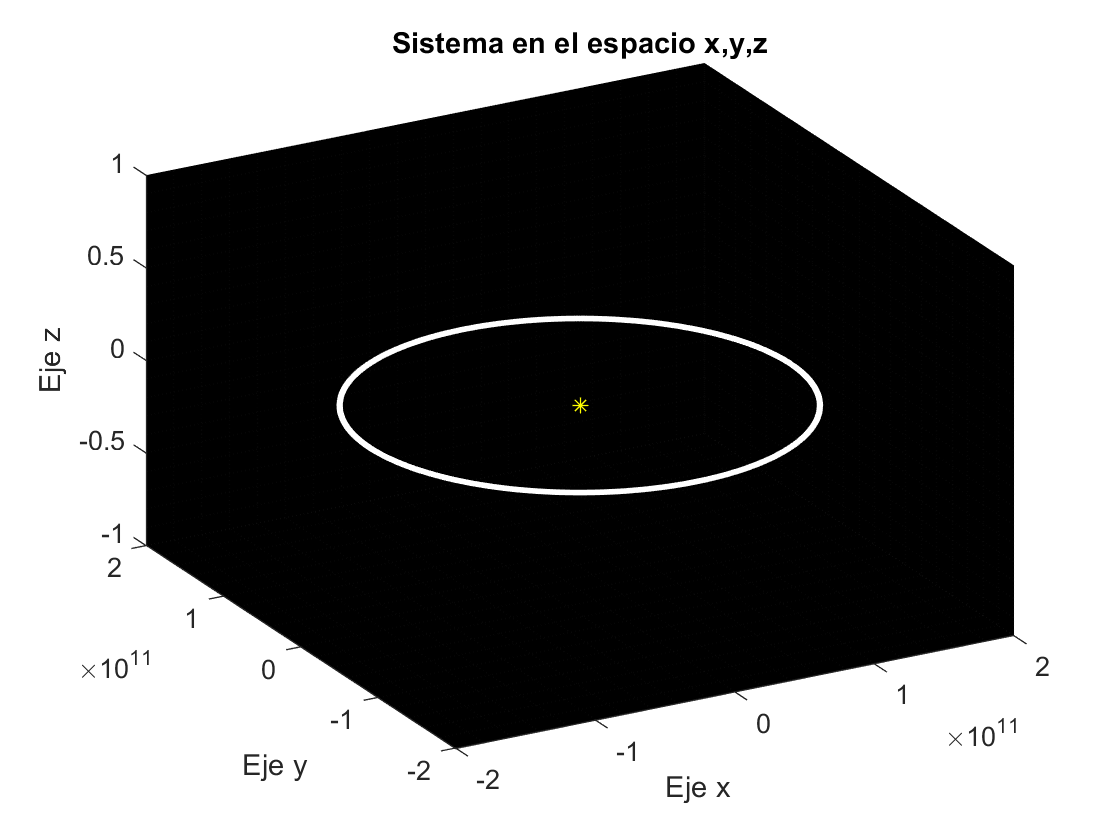


global G m;
G = 6.67408E-11;              % m3 kg-1 s-2
mS = 1.989e30;                % masa de Sol
mT = 5.9736e24;               % masa de Tierra
mL = 7.349e22;                % masa de la Luna
m = [mS, mT, mL]; 

rS = 695.510e6;               % radio del Sol m
rT = 6371e3;                  % radio de la Tierra m
hT = 149.6e9;                 % altura de la superficie del Sol a la Tierra
hL = 384400e3;                % altura de la superficie de la Tierra a la Luna

r0 = [[0,0,0]; [rS+hT,0,0]; [rS+hT+2*rT+hL,0,0] ];  %ver notación y contrucción de vectores
% Nuestro sistema parte de que el Sol esta en el origen y a partir de esto, se calculan las demás
% posiciones iniciales.

vT = sqrt(G * m(1)/r0(2,1));                        %velocidad de la Tierra
vL1 = sqrt(G * m(1)/r0(3,1));                       %velocidad de la Luna con respecto al Sol
vL2 = sqrt(G * m(2)/(rT+hL));                       %velocidad de la Luna con respecto a la Tierra

% Todos los objetos se mueven sobre el plano x,y. Nosotros consideramos despreciable la velocidad 
% de la Tierra con respecto a la Luna y contruimos la velocidad resultante de la Luna como una suma
% de vL1+vL2

v0 = [ [0,0,0]; [0,vT,0]; [0,vL1+vL2,0] ];          %ver notación y contrucción de vectores

wT = vT/(rS+hT);              % velocidad angular de la Tierra
wL = vL2/(rT+hL);             % velocidad angular de la Luna
 
TT = (2*pi)/wT;               % periodo Tierra
TL = (2*pi)/wL;               % periodo Luna
 
h = 6000;                     % paso entre cada unidad de tiempo
nv = 5;                       % numero de vueltas a calcular
NkT = nv*ceil(TT/h);          % tiempo final que define el total de puntos a tomar de la Tierra
NkL = nv*ceil(TL/h);          % tiempo final que define el total de puntos a tomar de la Luna

% Notar, estaremos usando NKT para hacer todos los cálculos debido a que es mayor que NkL y deseamos
% graficar el mismo número de puntos tanto para la Tierra, como la Luna.


y0 = [r0;v0];

% Esto es un rk4, este método se cambia para poder utilizar ivps de forma general.
% para probar rk4 descomenta el siguiente renglon más la función que se encuentra al final del código
% debes comentar ivps y ls declaracion de pos que esta abajo de esta.
% pos = rk4(@f1, NkT, y0, pos, h);

% Uso de ivps para resolver el sistema
[t,y] = ivps(@f1,0, h*NkT, y0, h, 4);

% ivps regrea tanto r como v dentro de un vector y, por esto tomatemos solo los primeros tres valores que
% son las posiciones
pos = y(1:3, :);

% pos guarda los valores de las posiciones de los tres cuerpos de forma horizontal (ver construccion de vectores)
% entonces, para poder graficar cada punto, nos fue mas facil colocar las posiciones de forma vertical
% para cada punto (x,y,z). Hicimos esto porque si dejabamos las posiciones en horizontal, teniamos
% el problema de que habia tomar las x con las x, las y con las y, y las z con las z.
% Entonces, en forma vertical (pos2) al graficar podemos tomar todos los puntos en un renglon
% sabiendo que en cada renglon estan todas las x, todas las y o todas las z de un cuerpo particular, segun 
% el renglon que sea. (Ver construccion de vectores)

% Entonces, este for pasa el vector pos de forma horizontal a un vector pos2 de forma vertical.
pos2 = zeros(9,NkT+1);

for i = 1:3:3*(NkT+1)
    pos2(:,(i+2)/3) = [pos(1,i); pos(1,i+1);pos(1,i+2); pos(2,i); pos(2,i+1);pos(2,i+2); pos(3,i); pos(3,i+1);pos(3,i+2)];
end

hold on;
plot3(pos2(1,:),pos2(2,:),pos2(3,:),'*y');       %Graficamos todos los puntos x,y,z del Sol
plot3(pos2(4,:),pos2(5,:),pos2(6,:),'b');        %Graficamos todos los puntos x,y,z de la Tierra
plot3(pos2(7,:),pos2(8,:),pos2(9,:),'.w');       %Graficamos todos los puntos x,y,z de la Luna
grid minor;
title("Sistema en el espacio x,y,z");
xlabel('Eje x');
ylabel('Eje y');
zlabel('Eje z');
view([-29 32]);                                  %Esta es la vista del espacio x,y,z
set(gca,'Color','k')

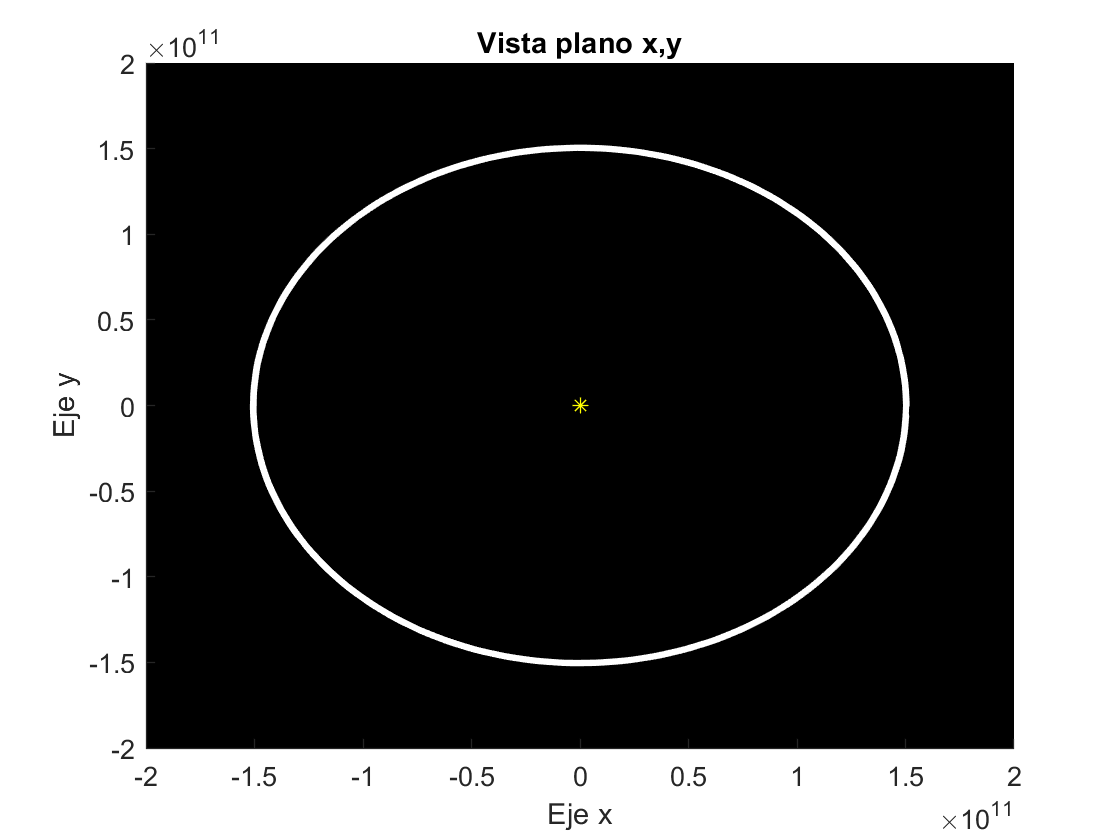

hold on;
plot3(pos2(1,:),pos2(2,:),pos2(3,:),'*y');       %Graficamos todos los puntos x,y,z del Sol
plot3(pos2(4,:),pos2(5,:),pos2(6,:),'b');        %Graficamos todos los puntos x,y,z de la Tierra
plot3(pos2(7,:),pos2(8,:),pos2(9,:),'.w');       %Graficamos todos los puntos x,y,z de la Luna
grid minor;
title("Vista plano x,y");
xlabel('Eje x');
ylabel('Eje y');
zlabel('Eje z');
view([0.60 90.00]);                              %Esta es la vista del plano x,y

set(gca,'Color','k')

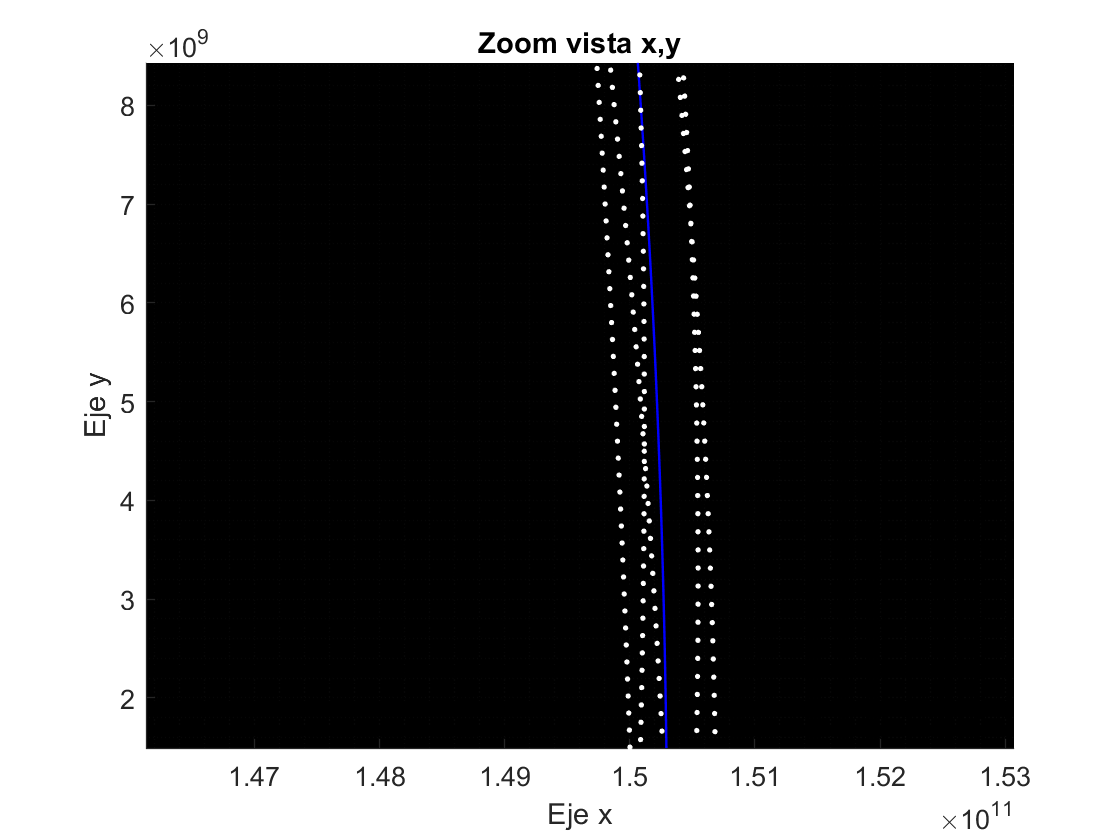

hold on;
plot3(pos2(1,:),pos2(2,:),pos2(3,:),'*y');       %Graficamos todos los puntos x,y,z del Sol
plot3(pos2(4,:),pos2(5,:),pos2(6,:),'b');        %Graficamos todos los puntos x,y,z de la Tierra
plot3(pos2(7,:),pos2(8,:),pos2(9,:),'.w');       %Graficamos todos los puntos x,y,z de la Luna
grid minor;
view([0.60 90.00]);                              %Esto es un zoom en la vista del plano x,y.
title("Zoom vista x,y");
xlabel('Eje x');
ylabel('Eje y');
zlabel('Eje z');
xlim([146133701250 153070313217]);
ylim([1491672676 8428284642]);
zlim([-0.0173 0.0173]);

set(gca,'Color','k')

function ydot = f1(~,y)
  global G m;                 
  r = y(1:3,:);
  v = y(4:6,:);
  
  drA = r(2,:) - r(1,:);         %Sol vs Tierra
  uA = drA / norm(drA);            
  drA2 = norm(drA)^2;         	 
  FA = (G*m(1)*m(2)/drA2) * uA;    
  
  drB = r(3,:) - r(1,:);         %Sol vs Luna
  uB= drB / norm(drB);            
  drB2 = norm(drB)^2;         	 
  FB = (G*m(1)*m(3)/drB2) * uB;    
  
  drC = r(3,:) - r(2,:);         %Luna vs Tierra
  uC= drC / norm(drC);            
  drC2 = norm(drC)^2;         	 
  FC = (G*m(2)*m(3)/drC2) * uC;    
  
  a = [(FA+FB)/m(1); -(FA-FC)/m(2); -(FB+FC)/m(3)];       %F = m.a
  
  ydot = [v;a];
end

% la función queda comentada porque no se utilizará.

% function pos = rk4(f, Nk, y, pos, h)
%     for t=4:3:3*(Nk+1)
%       s1 = f(t,y);
%       s2 = f(t+h/2,y+(h/2)*s1);
%       s3 = f(t+h/2,y+(h/2)*s2);
%       s4 = f(t+h, y+h*s3);
%       slope = (s1+2*s2+2*s3+s4)/6;
%       y = y + slope*h;
%     
%       r = y(1:3,:); 
%       pos(:,t:t+2) = [r(1,:); r(2,:); r(3,:)];  
%     end
% end
